# Sequence-to-Sequence Classification Using 1-D Convolutions

This example shows how to classify each time step of sequence data using a generic temporal convolutional network (TCN).

PRJ: see also NN models published here: [https://paperswithcode.com/paper/eegnet-a-compact-convolutional-network-for](https://paperswithcode.com/paper/eegnet-a-compact-convolutional-network-for) 

clear all; close all;

## Loading all the data

collectedElectrodes = ["C3", "Cz", "C4"]; % or just simple string "all"
% collectedElectrodes = "all";

DataSetB = EEGDataSet_chunks("../data/hands/BCICIV_calib_ds1b.mat", collectedElectrodes);
DataSetG = EEGDataSet_chunks("../data/hands/BCICIV_calib_ds1g.mat", collectedElectrodes);


Data organization and splitting into training/validation/testing:

tempInputs = [
    DataSetB.EEGToLoad;
    DataSetG.EEGToLoad
    ];

tempOutputs = [
    DataSetB.signalsCueCategoricalOUTPUT;
    DataSetG.signalsCueCategoricalOUTPUT;
    ];

% Filter for strictly equal chunk length:
Inputs = filterHands(tempInputs);
Outputs = filterHands(tempOutputs);


Divide data randomly into **train**, **test** and **validation** datasets

%PRJ - todo: load all data first and then divide it using 'dividerand' to
%define train, test and validation datasets
nChunks=numel(Outputs);
[trainInd,valInd,testInd] = dividerand(nChunks,0.8,0,0.2);
 
InTrain = Inputs(1,trainInd);
OutTrain= Outputs(1,trainInd);
% InValid = Inputs(1,valInd);
% OutValid= Outputs(1,valInd);
InTest  = Inputs(1,testInd);
OutTest= Outputs(1,testInd);


## Define Deep Learning Model

The main building block of a TCN is a dilated causal convolution layer, which operates over the time steps of each sequence. In this context, "causal" means that the activations computed for a particular time step cannot depend on activations from future time steps. 

To build up context from previous time steps, multiple convolutional layers are typically stacked on top of each other. To achieve large receptive field sizes, the dilation factor of subsequent convolution layers is increased exponentially, as shown in the following image. Assuming that the dilation factor of the k-th convolutional layer is $2^{\left(k-1\right)}$ and the stride is 1, then the receptive field size of such a network can be computed as $R=\left(f-1\right)\left(2^K -1\right)+1$, where $f$ is the filter size and $K$ is the number of convolutional layers. Change the filter size and number of layers to easily adjust the receptive field size and the number of learnable parameters as necessary for the data and task at hand.

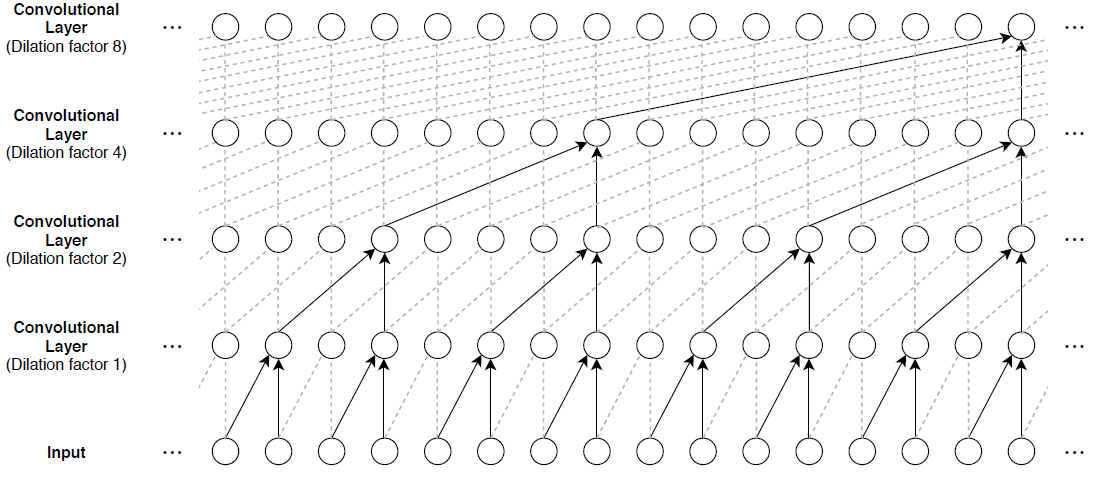

One of the disadvantages of TCNs compared to recurrent networks is that they have a larger memory footprint during inference. The entire raw sequence is required to compute the next time step. To reduce inference time and memory consumption, especially for step-ahead predictions, train with the smallest sensible receptive field size $R$ and perform prediction only with the last $R$ time steps of the input sequence.

The general TCN architecture (as described in [1]) consists of multiple residual blocks, each containing two sets of dilated causal convolution layers with the same dilation factor, followed by normalization, ReLU activation, and spatial dropout layers. The network adds the input of each block to the output of the block (including a 1-by-1 convolution on the input when the number of channels between the input and output do not match) and applies a final activation function.

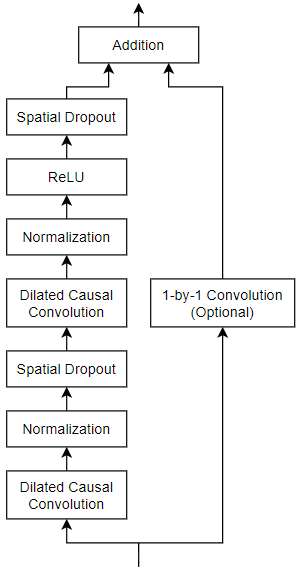

Define a network containing four of these residual blocks in series, each with double the dilation factor of the previous layer, starting with a dilation factor of 1. For the residual blocks, specify 64 filters for the 1-D convolutional layers with a filter size of 5 and a dropout factor of 0.005 for the spatial dropout layers. For spatial dropout, use the custom layer `spatialDropoutLayer`, attached to this example as a supporting file. To access this layer, open this example as a live script.

numFilters = 32; %16; %64;
% numFeatures = numel(elToConsider);
% Right now it is (and probably all the time it will be) 3
% Also manually add nClasses since commented in the beginning
nClasses = 2;
numFeatures = 3;
filterSize = 5; %PRJ / 5;
dropoutFactor = 0.1;
numBlocks = 4; %PRJ/ 4;

layer = sequenceInputLayer(numFeatures,Normalization="rescale-symmetric",Name="input");
lgraph = layerGraph(layer);

outputName = layer.Name;

for i = 1:numBlocks
    dilationFactor = 2^(i-1);

    layers = [
        convolution1dLayer(filterSize,numFilters,DilationFactor=dilationFactor,Padding="causal",Name="conv1_"+i)
        layerNormalizationLayer
        spatialDropoutLayer(dropoutFactor)
        convolution1dLayer(filterSize,numFilters,DilationFactor=dilationFactor,Padding="causal")
        layerNormalizationLayer
        leakyReluLayer %reluLayer
        spatialDropoutLayer(dropoutFactor)
        additionLayer(2,Name="add_"+i)];

    % Add and connect layers.
    lgraph = addLayers(lgraph,layers);
    lgraph = connectLayers(lgraph,outputName,"conv1_"+i);

    % Skip connection.
    if i == 1
        % Include convolution in first skip connection.
        layer = convolution1dLayer(1,numFilters,Name="convSkip");

        lgraph = addLayers(lgraph,layer);
        lgraph = connectLayers(lgraph,outputName,"convSkip");
        lgraph = connectLayers(lgraph,"convSkip","add_" + i + "/in2");
    else
        lgraph = connectLayers(lgraph,outputName,"add_" + i + "/in2");
    end

    % Update layer output name.
    outputName = "add_" + i;
end

layers = [
    fullyConnectedLayer(nClasses,Name="fc")
    softmaxLayer
    classificationLayer];
lgraph = addLayers(lgraph,layers);
lgraph = connectLayers(lgraph,outputName,"fc");

View the network in a plot.

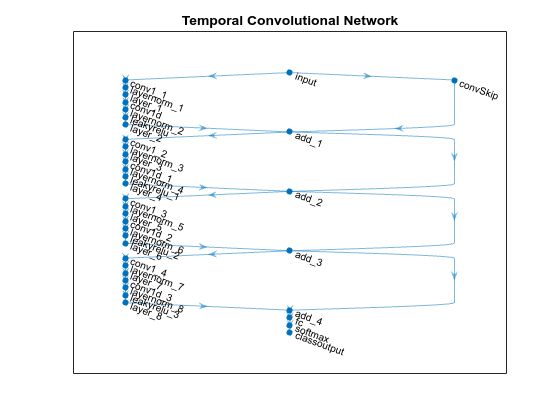

figure
plot(lgraph)
title("Temporal Convolutional Network")

## Specify Training Options

Specify a set of options used for training.

- Train for 60 epochs with a mini-batch size of 1.

- Train with a learning rate of 0.001.

- Display the training progress in a plot and suppress the verbose output.

options = trainingOptions("adam", ...
    MaxEpochs=200, ...
    miniBatchSize=20, ...
    ValidationData={InTest,OutTest}, ...
    ValidationFrequency=100, ...
    Plots="training-progress", ...
    Shuffle="every-epoch", ...
    Verbose=true);

% options = trainingOptions("adam", ...
%     MaxEpochs=200, ...
%     miniBatchSize=20, ...
%     Plots="training-progress", ...
%     Shuffle="every-epoch", ...
%     Verbose=true);

## Train Model

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       56.13% |       57.35% |       1.1821 |       1.1324 |          0.0010 |
|       4 |          50 |       00:00:07 |       46.92% |              |       0.7464 |              |          0.0010 |
|       8 |         100 |       00:00:11 |       59.90% |       56.93% |       0.6577 |       0.6748 |          0.0010 |
|      11 |         150 |       00:00:15 |       64.69% |              |       0.6266 |   

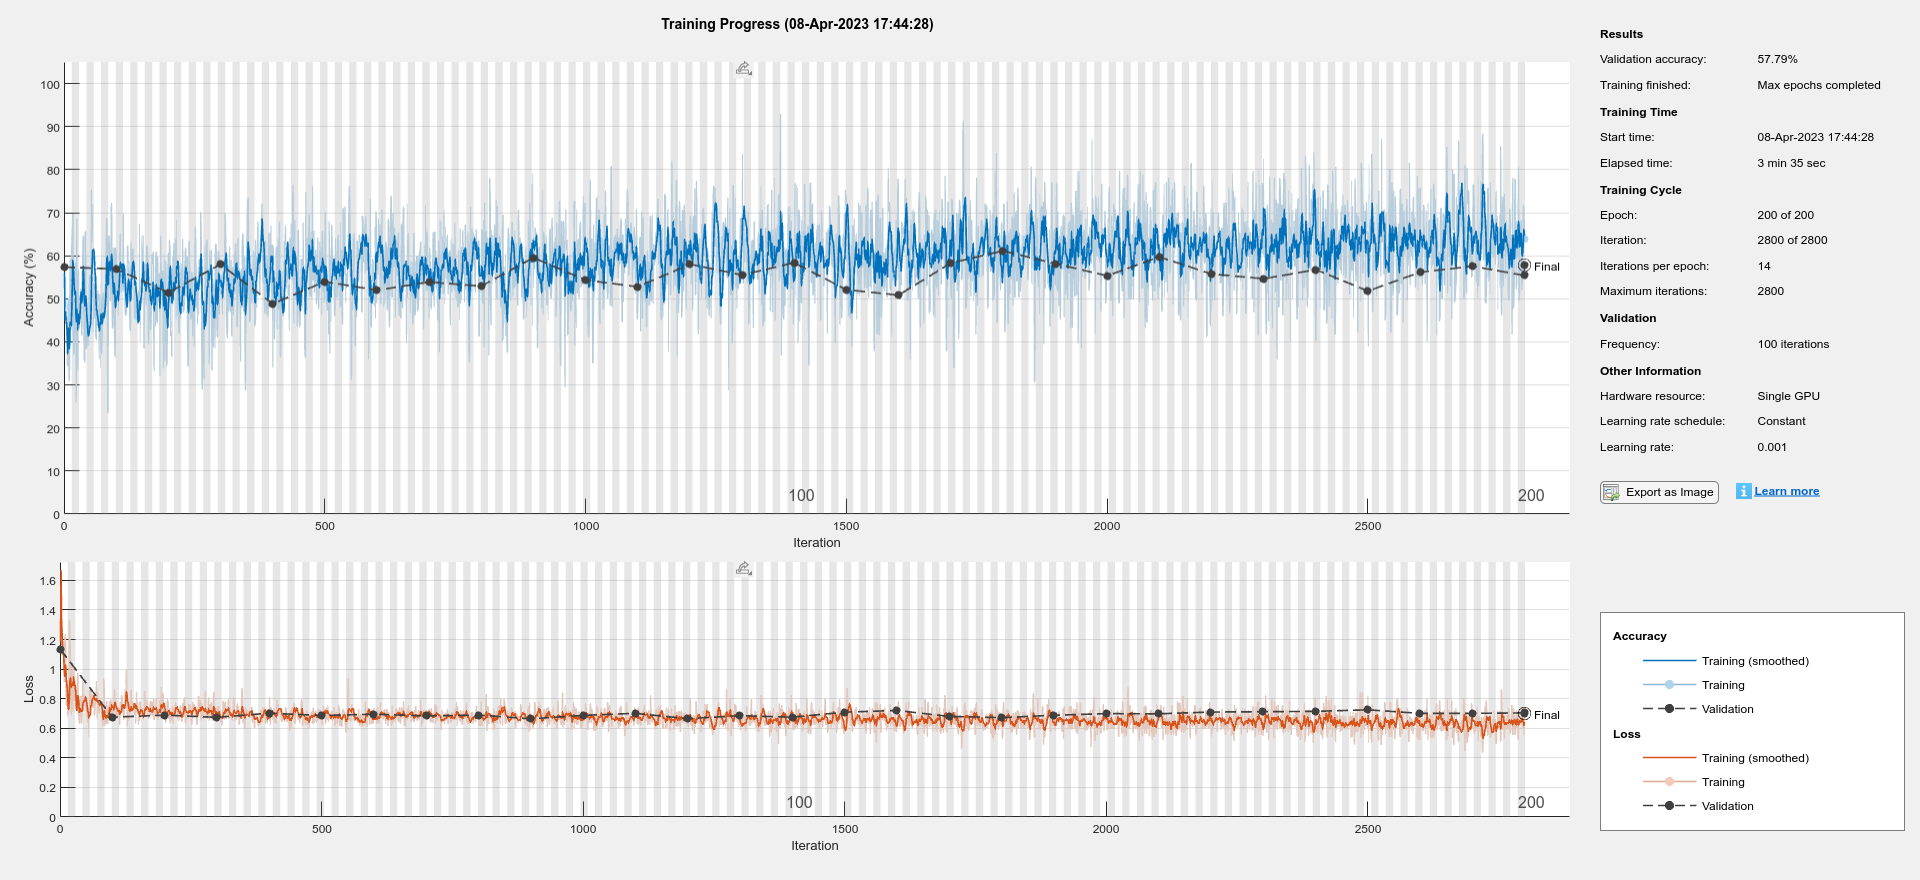

net = trainNetwork(InTrain,OutTrain,lgraph,options);

## Train more

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       56.64% |       56.18% |       0.6930 |       0.6948 |          0.0010 |
|       4 |          50 |       00:00:05 |       65.31% |              |       0.6302 |              |          0.0010 |
|       8 |         100 |       00:00:09 |       64.87% |       58.14% |       0.6281 |       0.6915 |          0.0010 |
|      11 |         150 |       00:00:12 |       59.41% |              |       0.6249 |   

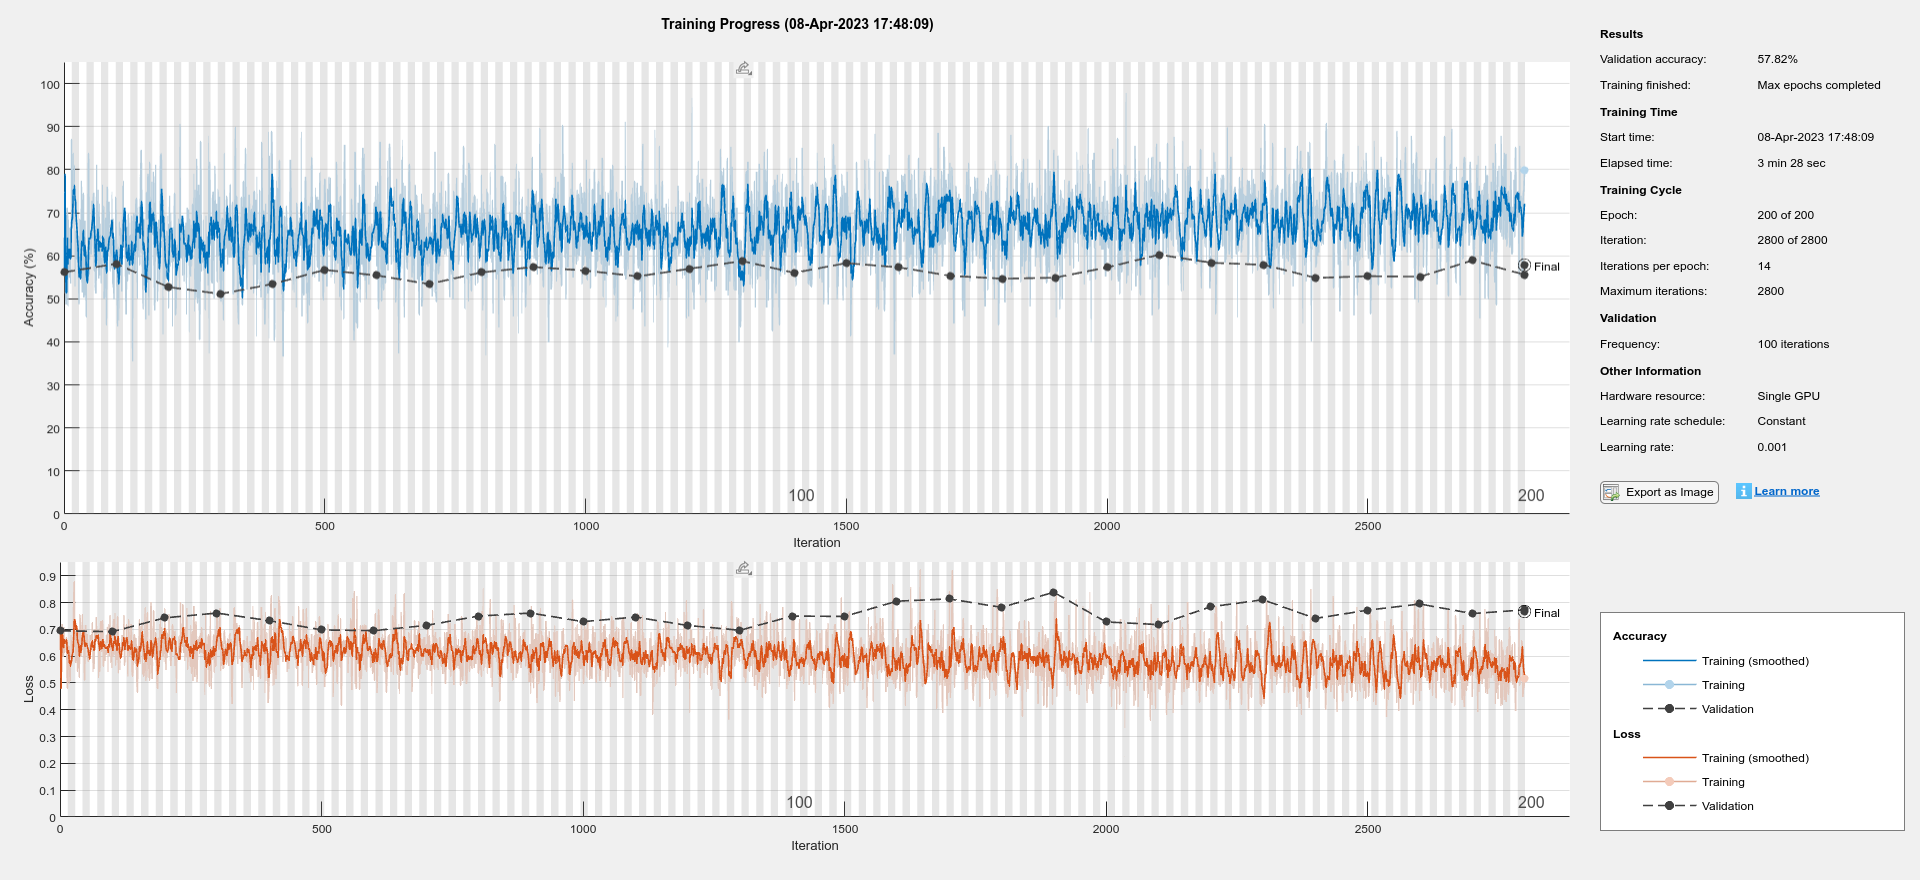

net = trainNetwork(InTrain,OutTrain,layerGraph(net),options);

save('net1.mat',"net");

## Test Model

Test the classification accuracy of the model by comparing the predictions on a held-out test set with the true labels for each time step. 

Use the trained network to make predictions by using the `classify` function.

OutPred = classify(net,InTest);

Visualize the predictions for **each sample** in a confusion matrix.

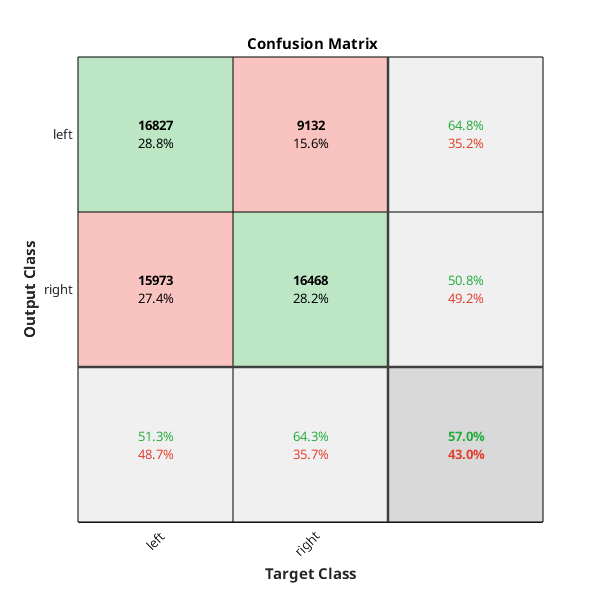

Pred = vertcat(OutPred{:});
True = vertcat(OutTest{:});
plotconfusion(True(:),Pred(:));

Visualize the predictions for **each sample** in a confusion matrix.

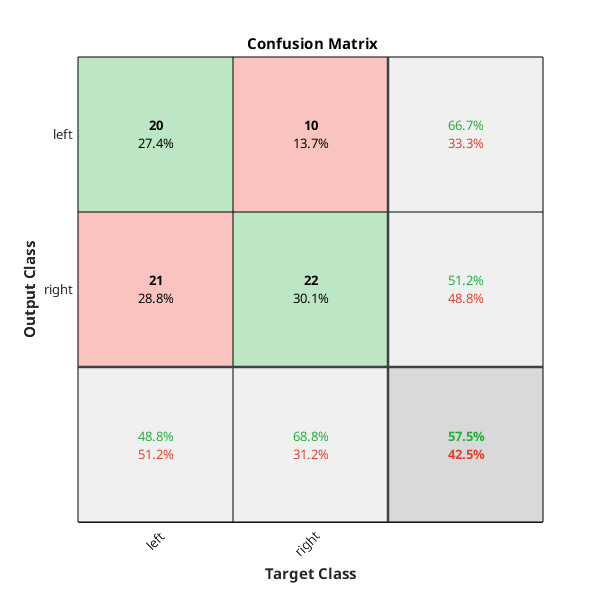

Pred = vertcat(OutPred{:});
True = vertcat(OutTest{:});
PredCount = countcats(Pred');
Predictions=1*(PredCount(1,:)<PredCount(2,:));
PredChunk = categorical(Predictions,[0 1],{'left', 'right'});
TrueChunk = True(:,1);
plotconfusion(TrueChunk(:),PredChunk(:));